# Modeling and Hardware-in-the-Loop (HIL) Testing of Physical Systems using Simscape

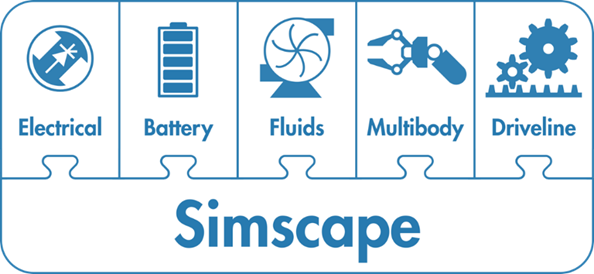    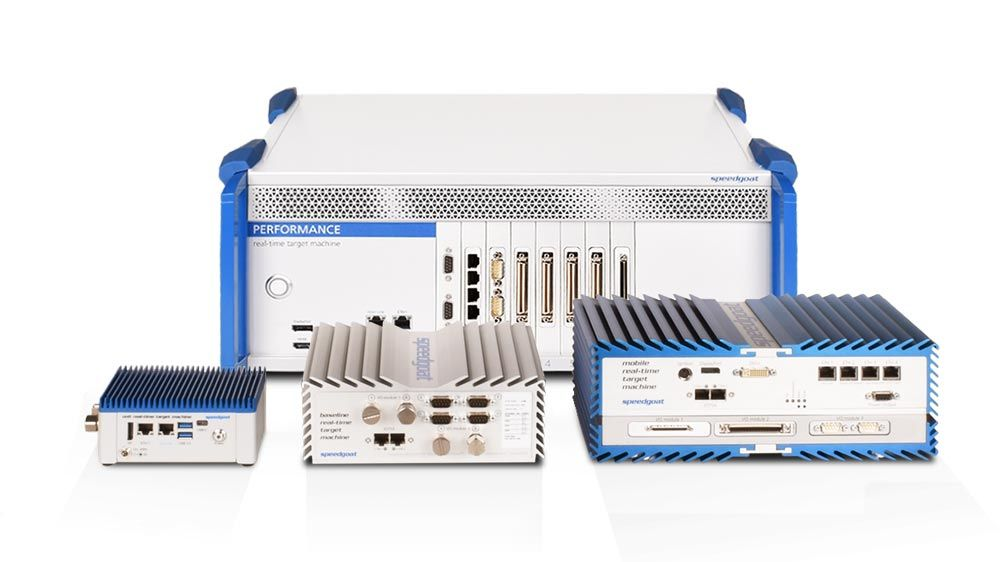

## Introduction to Simscape (10 minutes)

Enable physical modeling of multidomain physical systems

- Assemble a schematic

- Equations derived automatically

- Leverage MATLAB and Simulink

With Simscape, you can:

- Refine requirements for system

- Discover integration issues early

- Design control systems and logic

- Optimize system-level performance

- Test embedded software without hardware prototypes

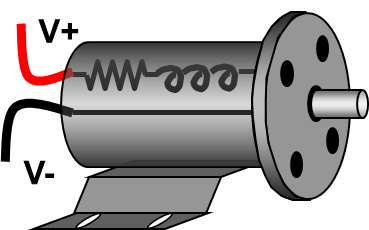        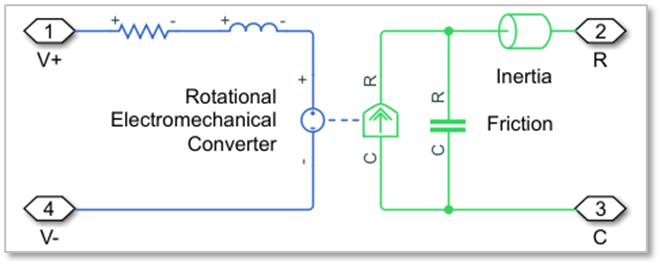

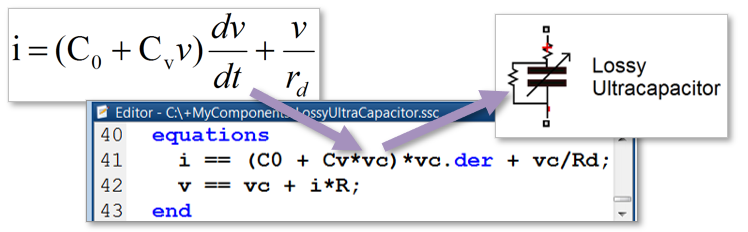

slLibraryBrowser

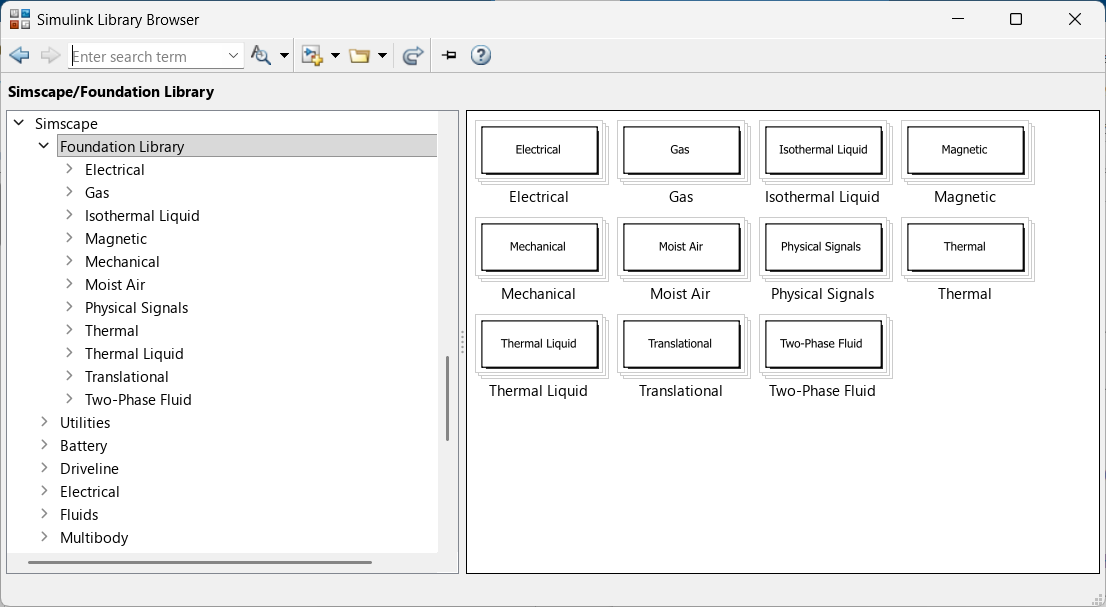         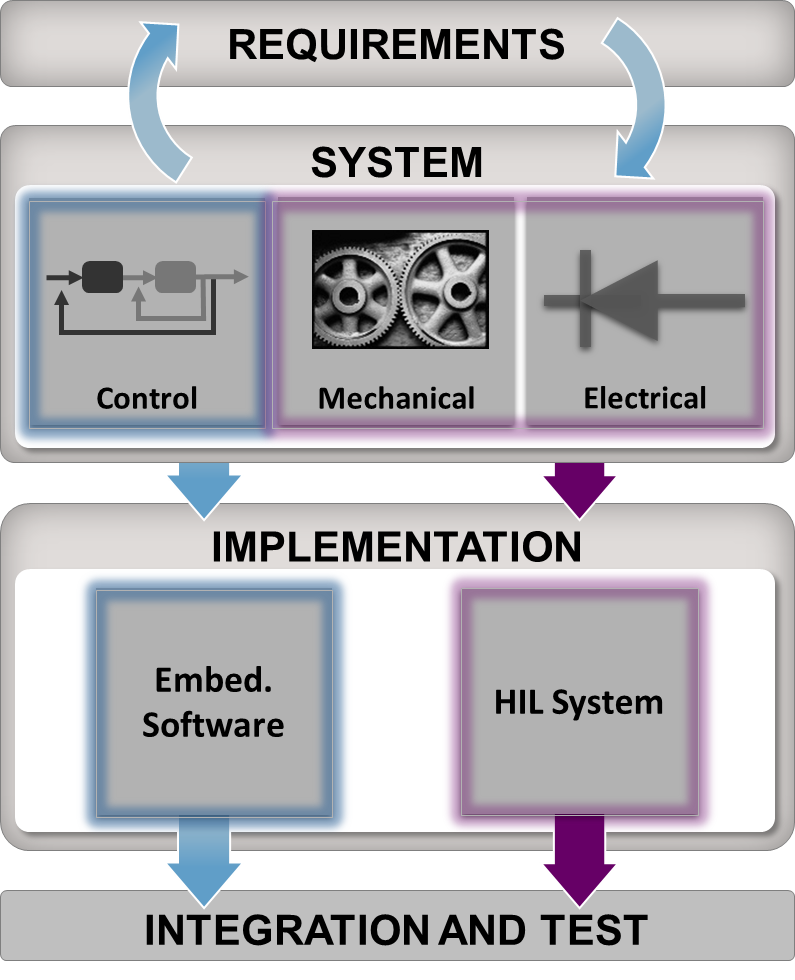

Simscape offers a comprehensive environment for physical modeling, providing a wide array of foundation blocks that span over ten different physical domains. Beyond the standard blocks, Simscape allows users to create custom components through its dedicated Simscape language.

The diagram above shows an electrohydraulic servo-valve created from Simscape components. For applications requiring real-time performance, Simscape provides specialized solvers optimized for this purpose.

Simscape supports C-code generation, enabling users to test embedded controllers in a simulated environment.

## Building your First Simscape Model (30 minutes)

This library contains blocks that model systems from many physical domains: electrical, mechanical, fluid, thermal, and more. In the first exercise, you will use blocks from Simscape Foundation Library to model physical systems, specifically to build a mass spring damper.

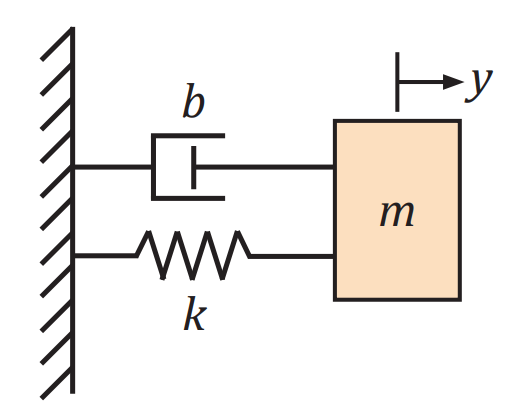

open("E01_Mass_spring_damper.slx")

In this exercise, you will model physical systems specifically using elements from the electrical domain to build an RC circuit. 

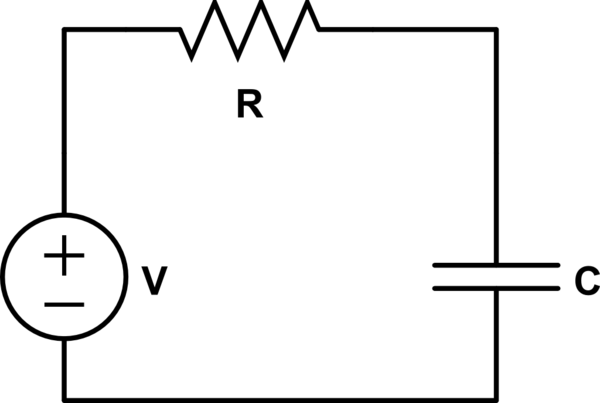

open("E02_RC_circuit.slx")

**Solver Configuration**

A Solver Configuration block must be connected to every Simscape physical network in your Simulink model. This block provides additional solver options and settings that can be configured for each physical network. Your Simulink model may contain more than one physical network.

[https://www.mathworks.com/help/releases/R2025b/simscape/ref/solverconfiguration.html?searchHighlight=Solver%20Configuration&searchResultIndex=1](https://www.mathworks.com/help/releases/R2025b/simscape/ref/solverconfiguration.html?searchHighlight=Solver%20Configuration&searchResultIndex=1)

## Parameterization and Real-World Data Integration (20 minutes)

In this example, we will model real capacitor (ECA-1CM100) which can be found in the datasheet: 

[https://industrial.panasonic.com/cdbs/www-data/pdf/RDF0000/ABA0000C1218.pdf](https://industrial.panasonic.com/cdbs/www-data/pdf/RDF0000/ABA0000C1218.pdf)

The extracted parameters are:

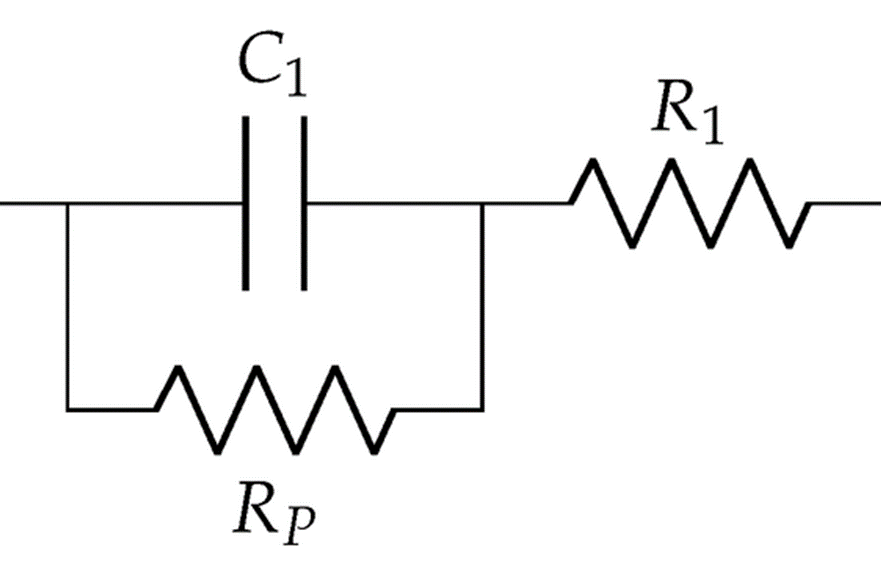

% Real component values
C = 10e-6;
ESR = 2.6;
V_rated = 16;
I_leakage = 3e-6;
R_leakage = V_rated/I_leakage;

% Simulation time
stop_time = 0.01;

open("E03_Real_RC_circuit.slx")

**Simulation Data Inspector**

Inspect and compare data and simulation results to validate and iterate model designs.

[https://www.mathworks.com/help/releases/R2025b/simulink/slref/simulationdatainspector.html?searchHighlight=data%20inspector&searchResultIndex=1](https://www.mathworks.com/help/releases/R2025b/simulink/slref/simulationdatainspector.html?searchHighlight=data%20inspector&searchResultIndex=1)

## Multidomain Modeling Exercise (30 minutes)

This model is based on a Faulhaber Series 0615 DC-Micromotor. The parameters values are set to match the 1.5V variant of this motor. The model uses these parameters to verify manufacturer-quoted no-load speed, no-load current, and stall torque.

When running the simulation, for the first 0.1 seconds the motor has no external load, and the speed builds up to the no-load value. Then at 0.1 seconds the stall torque is applied as a load to the motor shaft. The simulation results shows a good level of agreement with manufacturer data.

Often manufacturers do not quote the equivalent circuit parameters, and they must be estimated from information such as no-load speed, stall torque, and efficiency. A test harness such as this model can then be used to test the estimated equivalent circuit prior to using the motor model in a complete system simulation.

open("E04_PermanentMagnetDCMotor.slx")

**Simscape Result Explorer**

Navigate and plot simulation data logging results

[https://www.mathworks.com/help/releases/R2025b/simscape/ref/simscaperesultsexplorer.html?searchHighlight=simscape%20result%20explorer&searchResultIndex=1](https://www.mathworks.com/help/releases/R2025b/simscape/ref/simscaperesultsexplorer.html?searchHighlight=simscape%20result%20explorer&searchResultIndex=1)

## Integrating with Control Algorithms (15 minutes)

open("E05_PMDC_PID.slx")

## Demonstration - Speedgoat Hardware-in-the-Loop (HIL) (25 minutes)